% lab1script

% use the 'imread' command to read in an image
pout= imread('imageCE1.tif');

% If the image is black and white, this will create a two dimensional array
% of all of the image's pixel values.

% Note: when an image is read in to Matlab, it is of datatype uint8 (i.e.
% unsigned 8 bit integer)

% use the size command to find the dimensions of the image
[poutRows,poutCols]= size(pout)

poutRows = 576

poutCols = 768

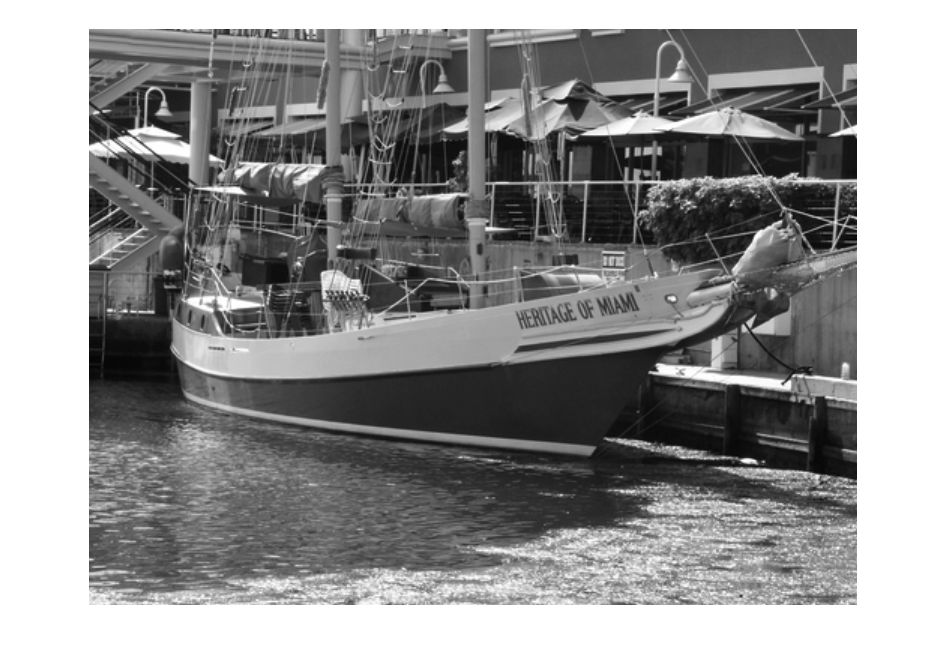


pause
%%%%%%%%%%%%%%%%%%%%


% use the 'imshow' command to display the image
figure
imshow(pout)


pause
%%%%%%%%%%%%%%%%%%%%

% Note: In order to use the imshow command, the image to display must be of
% datatype 'uint8'.  This command will display an all black or white image
% if the image is another datatype such as 'double'.  If you use any Matlab 
% tools to process an image, it is likely that the output will be a 
% 'double' instead of a 'unit8'.

% use the 'double()' command to cast a variable to data type 'double'
% use the 'uint8()' command to cast a variable to data type 'uint8'
% use the 'class' command to determine the data type of a variable

poutDouble= double(pout);
figure
imshow(poutDouble)


class(poutDouble)

ans = 'double'

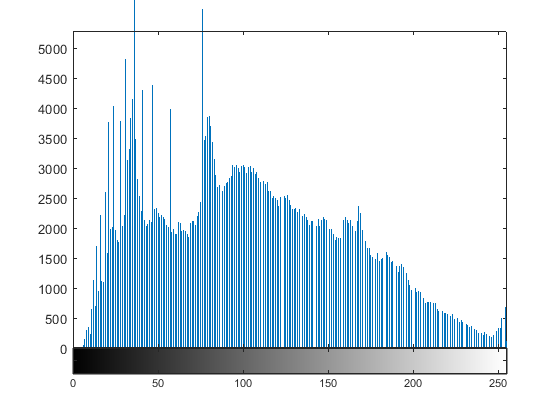

pause

imshow(uint8(poutDouble))
pause
%%%%%%%%%%%%%%%%%%%%


% if you have too many image windows open, you can use the 'close all'
% command to close all open Matlab figures

close all
pause
%%%%%%%%%%%%%%%%%%%%


% To examine a grayscale image's pixel value histogram, use the imhist
% command.

% Note: For imhist to work, the image must be of data type 'uint8'

imhist(pout)

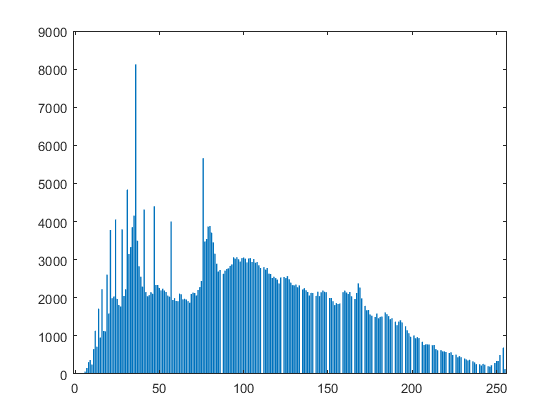


pause

% you can also use the 'imhist' command to return the histogram bin
% locations and values

[hval,pixval]= imhist(pout);

% you can then create a bar graph using these values (or use them for image
% analysis/processing)

figure
bar(pixval,hval)

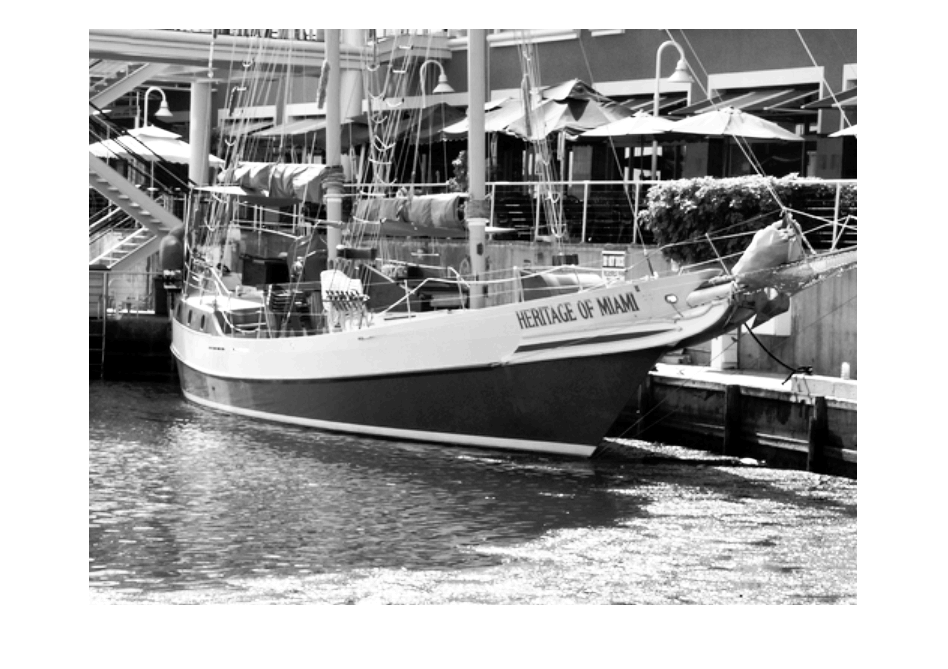


pause
close all
%%%%%%%%%%%%%%%%%%%%


% Use the 'histeq' command to perform histogram equalization on an image
poutHisEq= histeq(pout);

figure
imshow(poutHisEq)

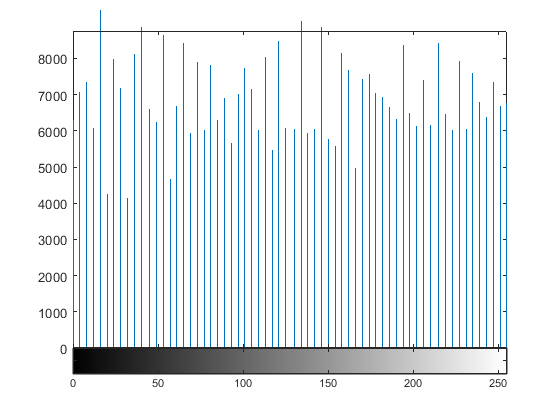

pause

figure
imhist(poutHisEq)

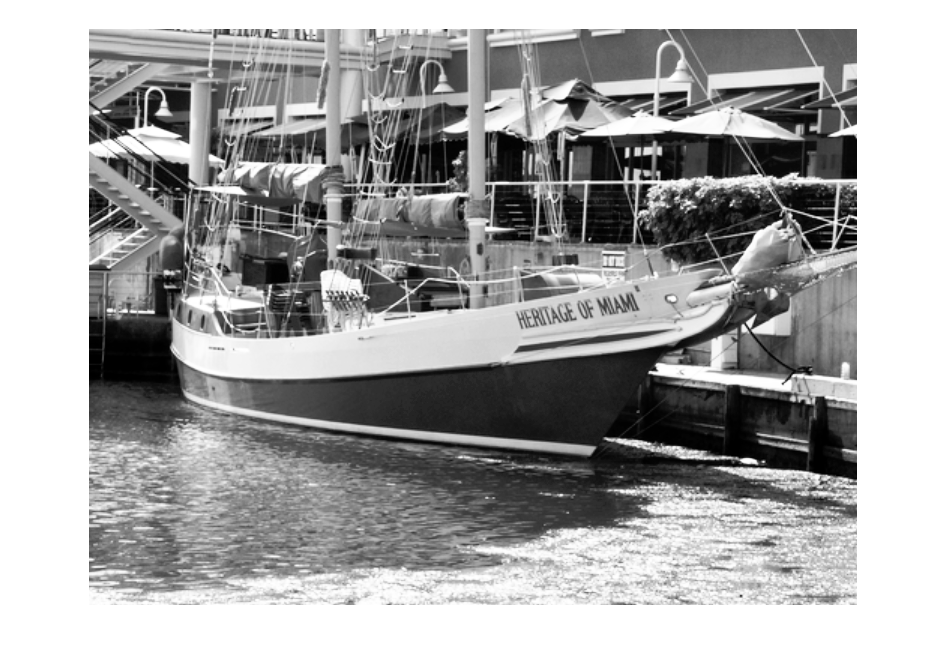

pause

% When performing histogram equalization, the 'histeq' command uses 64
% histogram bins by default.  However, you can specify the number of
% histogram bins that the function uses as follows:
poutHisEq2= histeq(pout,256);

figure
imshow(poutHisEq2)

pause

figure
imhist(poutHisEq2)
pause
close all
%%%%%%%%%%%%%%%%%%%%





